Author name: **Arjan Gupta**

Due date: March 20, 2023

Title of assignment in prompt: LE and Multi-link Manipulator

# Dynamics Equations for Multi-Link Manipulators

## Introduction

In this assignment, we aim to derive the equations of motion for 2 different types of manipulators. The equations of the motion take on the following form.


$$M\left(q\right)\ddot{q} \;+\;C\left(q,\dot{q} \right)\dot{q} \;+\;G\left(q\right)\;=\;\tau$$


Where, *M *is the mass matrix, *C* is the matrix of coriolis terms, and *G* is the matrix of gravitational forces. Also, $\ddot{q}$, $\dot{q}$, $q$ are the *n* dimensional vectors joint accelerations, joint velocities, and joint configurations. Here, *n* means the the number of joints we are considering. Sometimes, for simplicity, it is easier to only count the revolute joints as the total *n *and treat the prismatic joints simply as variable link lengths. This greatly simplifies the problem solving steps.

Furthermore, there are two methods to solve the problem (although they are really the same method, just organized differently). The first is the Lagrange-Euler  (LE) method, which is noted in the assignment prompt title as the expected way to solve this problem. The second way involves methodically finding the Coriolis terms.

## Problem 1

Figure

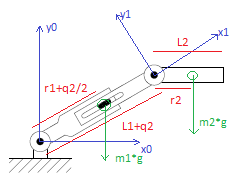

In this problem, we define $r_1$ as the distance between the world frame origin and the center of mass $m_1$ of the first link, $L_1 +q_2$, where $L_1$ is the fixed length and $q_2$ is the variable length due to the prismatic joint. Since the problem statement assumes that this link is has a mass with homogeneous density, we assume that the center of mass is always at half of the link length, so it is $r_1 +\frac{q_2 }{2}$ . The variable angle of the first joint is $q_1$. The second link has a constant length $L_2$, and a distance to center of mass $r_2$. The variable angle of the second joint is $q_2$.

### Solution A: E**xpected Way**

**Lagrange-Euler (LE) method**

clear; close all; clc;
syms r1 r2 q1 q2 q3 L1 L2

### Solution B: Extra Method

**Jacobian & Coriolis method**

clear; close all; clc;
syms r1 r2 q1(t) q2(t) q3(t) L1 L2 m1 m2 I1 I3

In this method, we take the following steps:

- Find linear Jacobians ($J_v$) for the center of mass of each link as an individual system

- Compute the kinetic energies of each link as an individual system, sum them to get *M* matrix 

- Generate the Coriolis terms for the *C* matrix

- Find the potential energy of each link as an individual system, sum them to get G matrix

- Combine the findings to produce the equations of motion

Step 1: Find linear Jacobians

% First link linear Jacobian
% q2 = 0;
z0 = [0;0;1];
zeros_vec = zeros(3,1);
on1 = [(r1 + q2/2)*cos(q1); (r1+ q2/2)*sin(q1); 0];
o0 = zeros_vec;
Jv1 = [cross(z0, (on1-o0)), zeros_vec];

% Second link linear Jacobian
z1 = z0;
o1 = [L1*cos(q1); L1*sin(q1); 0];
on2 = [(L1+q2)*cos(q1) + r2*cos(q1+q3); (L1 + q2)*sin(q1) + r2*sin(q1+q3); 0];
Jv2 = [cross(z0, (on2-o0)), cross(z1, (on2-o1))];

% Comment these in to view the jacobians
% disp(Jv1)
% disp(Jv2)

Step 2: Find kinetic energies

The kinetic energy of each link can be found using the formula $\frac{1}{2}{\dot{q} }^T \left\lbrace m{J_v }^T J_v +I\right\rbrace \dot{q}$, where *I* is the matrix for the moment of intertia. However, since we want to leave things in the matrix form, we only consider the $\left\lbrace m{J_v }^T J_v +I\right\rbrace$ portion. Our intertia matrices in this case are $\left\lbrack \begin{array}{cc}
I_1  & 0\\
0 & 0
\end{array}\right\rbrack$ and $\left\lbrack \begin{array}{cc}
I_3  & I_3 \\
I_3  & I_3 
\end{array}\right\rbrack$ corresponding to joints $q_1$ and $q_3$.

% First link KE
I1_mat = [I1 0; 0 0];
KE1_mat = m1*(Jv1.'*Jv1) + I1_mat;

% Second link KE
I2_mat = [I3 I3; I3 I3];
KE2_mat = m2*(Jv2.'*Jv2) + I2_mat;

% Our mass matrix is our total KE
M = KE1_mat + KE2_mat;
M = simplify(M);
display(M)

$$M(t) = \begin{array}{l} \left(\begin{array}{cc} I_{1}+I_{3}+\frac{m_{1}\,{q_{2}\left(t\right)}^{2}}{4}+\sigma_{2}+{L_{1}}^{2}\,m_{2}+m_{1}\,{r_{1}}^{2}+m_{2}\,{r_{2}}^{2}+m_{1}\,r_{1}\,q_{2}\left(t\right)+2\,L_{1}\,m_{2}\,q_{2}\left(t\right)+2\,m_{2}\,r_{2}\,\cos\left(q_{3}\left(t\right)\right)\,q_{2}\left(t\right)+2\,L_{1}\,m_{2}\,r_{2}\,\cos\left(q_{3}\left(t\right)\right) & \sigma_{1}\\ \sigma_{1} & m_{2}\,{r_{2}}^{2}+\sigma_{3}+\sigma_{2}+I_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{2}\,{r_{2}}^{2}+\sigma_{3}+L_{1}\,m_{2}\,\cos\left(q_{3}\left(t\right)\right)\,r_{2}+\sigma_{2}+L_{1}\,m_{2}\,q_{2}\left(t\right)+I_{3}\\ \sigma_{2}=m_{2}\,{q_{2}\left(t\right)}^{2}\\ \sigma_{3}=2\,m_{2}\,\cos\left(q_{3}\left(t\right)\right)\,r_{2}\,q_{2}\left(t\right) \end{array}$$

Step 3: Compute the Coriolis matrix

q_vec = [q1, q3].';
q_dot_vec = [diff(q1,t), diff(q3,t)].';
C = computeCoriolis(M(t), 2, q_vec(t), q_dot_vec(t));
C = simplify(C);
display(C)

$$C = \begin{array}{l} \left(\begin{array}{cc} -m_{2}\,r_{2}\,\sin\left(q_{3}\left(t\right)\right)\,\left(L_{1}+q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{3}\left(t\right) & -m_{2}\,r_{2}\,\sin\left(q_{3}\left(t\right)\right)\,\left(L_{1}+2\,q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{3}\left(t\right)-\sigma_{1}\\ \sigma_{1} & -m_{2}\,r_{2}\,\sin\left(q_{3}\left(t\right)\right)\,q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{3}\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{2}\,r_{2}\,\sin\left(q_{3}\left(t\right)\right)\,\left(L_{1}+q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right) \end{array}$$

## Supporting Functions

### Coriolis Computation

The following function output coriolis for the given parameters.

function C = computeCoriolis(M, n, q, q_dot)
    C = sym(zeros(n));
    for r = 1:n
        for c = 1:n
            for qi = 1:n
                C(r,c) = C(r,c) + q_dot(qi)*getCoriolisDiffCoeff(M,q,qi,c,r);
            end
        end
    end
end
function term = getCoriolisDiffCoeff(M,q,i,j,k)
    term = (1/2)*(diff(M(k,j),q(i)) + diff(M(k,i),q(j)) - diff(M(i,j),q(k)));
end